# Displacement Analysis

clear;
clc;

## Wild Type

WT = "";
[LuminalMeanDisplacement, MyoepithelialMeanDisplacement] = CellDisplacement(WT);

LuminalMeanDisplacement =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


MyoepithelialMeanDisplacement =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


time = double(importfile_time(WT));

#### Plot Time vs Average Cell Type Displacement

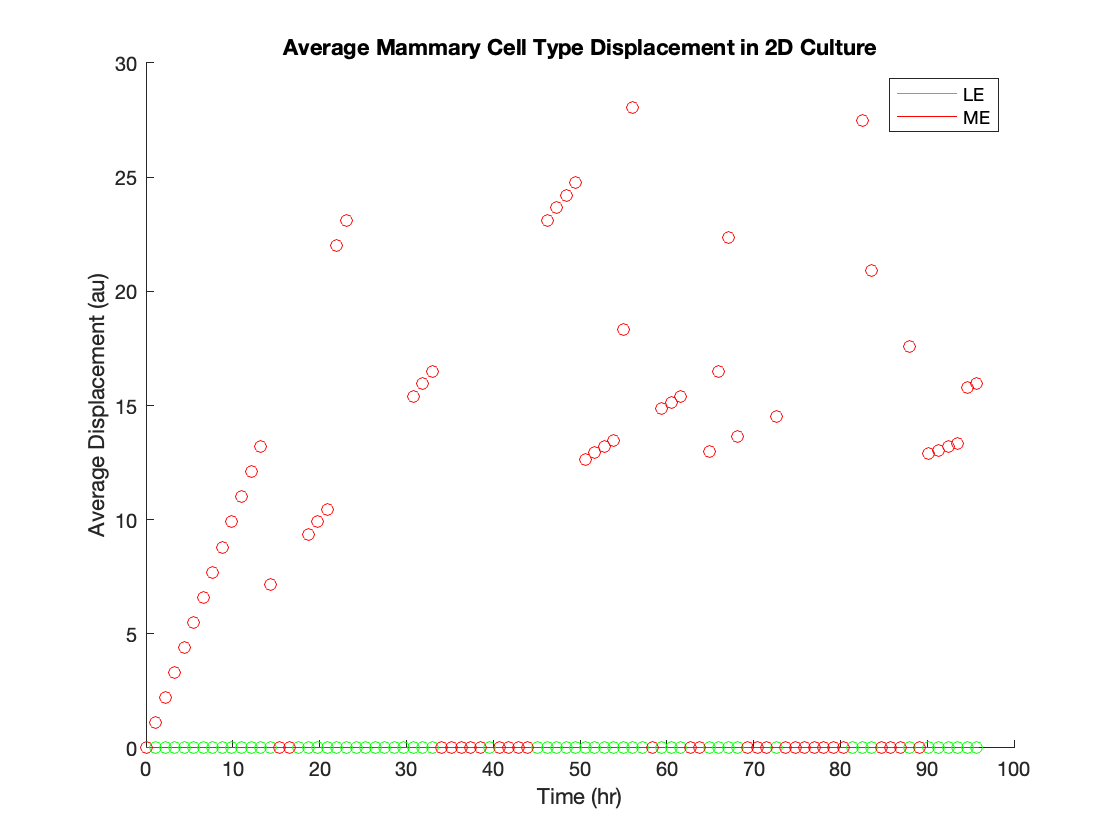

x = time(:,1);
yLE = LuminalMeanDisplacement(:,2);
BLE = filloutliers(yLE,'next','quartiles');

yME = MyoepithelialMeanDisplacement(:,2);
BME = filloutliers(yME,'next','quartiles');

figure
hold on

scatter(x(1:11:960),BLE(1:11:960),'green')
pLE = polyfit(x,BLE,3);
fLE = polyval(pLE,x);
LE = plot(x,fLE, 'g');

scatter(x(1:11:960),BME(1:11:960),'red')
pME = polyfit(x,BME,3);
fME = polyval(pME,x);
ME = plot(x,fME, 'r');

hold off

title ("Average Mammary Cell Type Displacement in 2D Culture")
xlabel("Time (hr)")
ylabel("Average Displacement (au)")
legend([LE, ME], 'LE', 'ME')

## B1 KO